% cd 'C:\GitHub\CVUT-MatLab\BnB'
clear;clc;startup;yalmip('clear')
tic

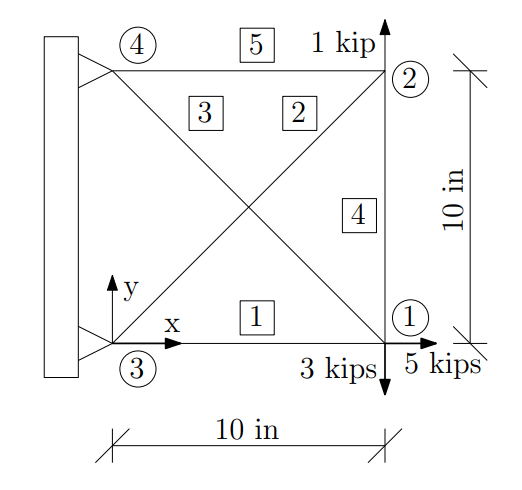

crossSectionsSet.A = [0.01;0.02;0.03;0.04;0.05;0.06;0.07;0.08;0.09;0.1];
crossSectionsSet.I = [0.01;0.02;0.03;0.04;0.05;0.06;0.07;0.08;0.09;0.1]*10^-4;
na = numel(crossSectionsSet.A);

## Ground structure

### Nodes

nodes.x = [10; 10; 0;  0];                       % x coordinates of nodes
nodes.y = [0;  10; 0; 10];                       % y coordinates of nodes
nodes.z = [0;   0; 0;  0];                       % z coordinates of nodes
nnodes  = numel(nodes.x);                           % number of nodes

### Elements

elements.nodes1 = [1;2;1;1;2];   % elements starting nodes
elements.nodes2 = [3;3;4;2;4];   % elements ending nodes
nelem = numel(elements.nodes1);  % number of elements  
nr = nelem;

### Groups of elements

elemGroup = [1;2;3;4;2];
ng = max(elemGroup);

plot3([nodes.x(elements.nodes1) nodes.x(elements.nodes2)]', ...
     [nodes.y(elements.nodes1) nodes.y(elements.nodes2)]', ...
     [nodes.z(elements.nodes1) nodes.z(elements.nodes2)]', ...
     'k','LineWidth',1);
hold on;
scatter3(nodes.x, nodes.y, nodes.z, 'blue', 'filled', 'o');
axis equal;
xlim([min(nodes.x)-1,max(nodes.x)+1]);  % to avoid tight limits
ylim([min(nodes.y)-1,max(nodes.y)+1]);  % to avoid tight limits
zlim([min(nodes.z)-1,max(nodes.z)+1]);  % to avoid tight limits
grid on
% view([180 90])
hold off;

### Material and cross-section

elements.E = 210*10^9 ;    % Young moduli of individual elements
elements.Rho = 7850;    

## Boundary conditions

### Restricted displacements

kinematic.x.nodes = [3; 4];             % node indices with restricted x-direction displacements
kinematic.y.nodes = [3; 4];             % node indices with restricted y-direction displacements
kinematic.z.nodes = [1;2;3;4];          % node indices with restricted z-direction displacements

### Load

loads.x.nodes = [1];             % node indices with x-direction forces
loads.x.value = [5000];             % magnitude of the x-direction forces
loads.y.nodes = [1;2];          % node indices with y-direction forces
loads.y.value = [-3000;1000];          % magnitude of the y-direction forces 
loads.z.nodes = [];             % node indices with z-direction forces
loads.z.value = [];             % magnitude of the z-direction forces 

### Boundary conditions

dofs = true(nnodes,3);                % no kinematic boundary conditions
dofs(kinematic.x.nodes,1) = false;    % mark prevented movement in x-direction
dofs(kinematic.y.nodes,2) = false;    % mark prevented movement in y-direction
dofs(kinematic.z.nodes,3) = false;    % mark prevented movement in z-direction
dofs = reshape(dofs.',[],1);
nd = sum(dofs,"all");

## Optimization parameters

maximumDisplacement = 0.06;
minimumDisplacement = -0.06;

### Design variables

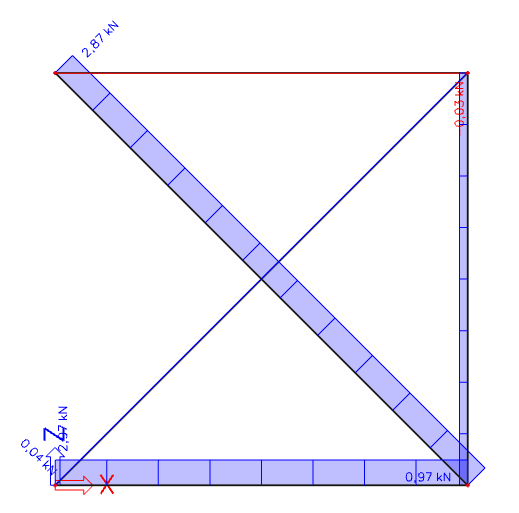

x = binvar(ng*na,1);
s = sdpvar(nr*na,1);
u = sdpvar(nd,1);  

## FEM

deltaX = nodes.x(elements.nodes2) - nodes.x(elements.nodes1);
deltaY = nodes.y(elements.nodes2) - nodes.y(elements.nodes1);
deltaZ = nodes.z(elements.nodes2) - nodes.z(elements.nodes1);
lengths = sqrt(deltaX.^2 + deltaY.^2 + deltaZ.^2);
cosinus = [deltaX./lengths deltaY./lengths deltaZ./lengths];
codeNumbers = [repmat(elements.nodes1,1,3) repmat(elements.nodes2,1,3)]*3-2 + repmat([0 1 2 0 1 2], nr, 1);
staticMatrix = sparse(codeNumbers(:), ...
                      repmat(1:nr,1,6), ...
                      [-cosinus(:,1); -cosinus(:,2); -cosinus(:,3); cosinus(:,1); cosinus(:,2); cosinus(:,3);], ...
                      nnodes*3, nr);
matrixB = full (staticMatrix(dofs,:) );

## Optimization problem formulation and solution

Fmax =  diag(kron( ones(nr,1) .* (elements.E*pi^2*lengths.^-2) , crossSectionsSet.I))
Fmin = -diag(kron( ones(nr,1) .* (elements.E*pi^2*lengths.^-2) , crossSectionsSet.I))
cmin = reshape((kron(elements.E*crossSectionsSet.A', 1 ./ lengths) .* (sum(((matrixB > 0) .* matrixB) .* minimumDisplacement)' + sum(((matrixB < 0) .* matrixB) .* maximumDisplacement)'))', 1, []);
Cmin = diag(cmin)
cmax = reshape((kron(elements.E*crossSectionsSet.A', 1 ./ lengths) .* (sum(((matrixB > 0) .* matrixB) .* maximumDisplacement)' + sum(((matrixB < 0) .* matrixB) .* minimumDisplacement)'))', 1, []);
Cmax = diag(cmax)
I = eye(nr * na);
B = kron(matrixB, ones(1, na));
K = kron ( kron ((elements.E./lengths), crossSectionsSet.A), ones(nd,1)') .* B';

Q = sparse(1:nr,elemGroup,1,nr,ng);
G = kron( Q, eye(na));
forceVector = sparse([loads.x.nodes*3-2; loads.y.nodes*3-1; loads.z.nodes*3], ...
                     1, ...
                     [loads.x.value; loads.y.value; loads.z.value ], ...
                     nnodes*3, 1);
f = forceVector(reshape(dofs.', 1, [])');
IM = zeros(nr, na * nr);
for j = 1:nr
        IM(j, na*(j-1)+1:na*(j)) = 1;
end


### Constraints

y = double2sdpvar(zeros(2*na*nr+ nd,1));
y(1:nr*na,1) = G*x;
y(1+nr*na:nr*na+nd,1) = u;
y(1+nr*na+nd:2*nr*na+nd,1) = s;

#### Constraint 1: Inequality


$$A_{ineq} y \leq b
$$


**Matrix **$A_{ineq}
$

Aineq = zeros(4*na*nr,2*nr*na+nd);

*First collumn*

Aineq(1:nr*na,1:nr*na)              =  Fmin;
Aineq(1+nr*na:2*nr*na,1:nr*na)      = -Fmax;
Aineq(1+2*nr*na:3*nr*na,1:nr*na)    = -Cmin;
Aineq(1+3*nr*na:4*nr*na,1:nr*na)    =  Cmax;

*Second collumn*

Aineq(1+2*nr*na:3*nr*na,1+nr*na:nr*na+nd)    =  K;
Aineq(1+3*nr*na:4*nr*na,1+nr*na:nr*na+nd)    = -K;

*Third collumn*

Aineq(1:nr*na,1+nr*na+nd:2*nr*na+nd)              = -I;
Aineq(1+nr*na:2*nr*na,1+nr*na+nd:2*nr*na+nd)      =  I;
Aineq(1+2*nr*na:3*nr*na,1+nr*na+nd:2*nr*na+nd)    =  I;
Aineq(1+3*nr*na:4*nr*na,1+nr*na+nd:2*nr*na+nd)    = -I;

**Vector **$b
$

b = zeros(4*na*nr,1);
b(1+2*nr*na:3*nr*na,1) = -diag(Cmin);
b(1+3*nr*na:4*nr*na,1) =  diag(Cmax);
constIneq = [Aineq * y <= b]:'Nerovnost';

#### Constraint 2: Equality


$$A_{eq} y = b_{eq}
$$


**Matrix **$A_{eq}
$

Aeq = zeros(nd + nr,2*nr*na+nd);
Aeq(nd+1:nd+nr,1:nr*na) = IM;
Aeq(1:nd,nr*na+nd+1:nr*na+nd+nr*na) = B;


**Vector **$b_{eq}$

beq = zeros(nd + nr,1);
beq(1:nd,1) = f;
beq(nd+1:nd+nr,1) = ones(nr,1);
constEq = [Aeq * y == beq]:'Rovnost';

#### Constraint 3: Box constraints

***Lower bound***

lb = zeros(nr*na*2+nd,1);
lb(1:nr*na) = 0;
lb(nr*na+1:nr*na + nd) = minimumDisplacement;
lb(nr*na+nd+1:nr*na*2+nd) = -kron( ones(nr,1) .* (elements.E*pi^2*lengths.^-2) , crossSectionsSet.I);


**Upper bound**

ub = zeros(nr*na*2+nd,1);
ub(1:nr*na) = 1;
ub(nr*na+1:nr*na + nd) = maximumDisplacement;
ub(nr*na+nd+1:nr*na*2+nd) = kron( ones(nr,1) .* (elements.E*pi^2*lengths.^-2) , crossSectionsSet.I);

***Box constraint***

constBox = [(lb <= y)]:'Dolní mez' & [(y <= ub)]:'Horní mez';

### Objective function

m = elements.Rho * kron(lengths,ones(na,1))' .* kron(ones(nr,1),crossSectionsSet.A)';
M = sparse(1,nr*na*2 + nd);
M(1:nr*na) = m;
objective = M * y;

### Solution

ops = sdpsettings('solver', 'gurobi');  % Nastavení Gurobi solveru s metodou BnB
ops = sdpsettings(ops,'verbose',1,'debug',1);
constraints = [constIneq, constEq, constBox];  % Kombinace všech omezení
result = optimize(constraints, objective, ops);

## Post-procesing

### Write solution

fprintf('Optimized objective: %f\n', value(objective));
check(constraints)
vector = (G*value(x)).* repmat(1:na, 1, nr)';
vector(G*value(x)==1)

### Plotting

Plot the optimal design. Note that the dimensions are scaled.

crossSections = reshape(G*value(x), 10, 5)'*crossSectionsSet.A;
nonzeroAreas = value(crossSections)>0;
p = plot([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
         [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]');
set(p, {'LineWidth'}, num2cell(10*value(crossSections(nonzeroAreas))/max(value(crossSections))));
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
axis equal

## Basic FEM

% crossSections = reshape(G*value(x), 10, 5)'*crossSectionsSet.A;
% 
% staticMatrix(dofs,:)*diag(elements.E.*crossSections./lengths) *staticMatrix(dofs,:)';
% 
% stiffnessMatrix= staticMatrix(dofs,:)* diag(elements.E.*crossSections./lengths) *staticMatrix(dofs,:)';
% displacements = stiffnessMatrix\f;
% y = zeros(ng*na + na*nr+ nd,1);
% y(1:ng*na,1) = x;
% y(1+ng*na:ng*na+nd,1) = displacements;
% y(1+ng*na+nd:ng*na + nr*na+nd,1) = s;
% koo = (Aineq * y <= b)'
% f
toc